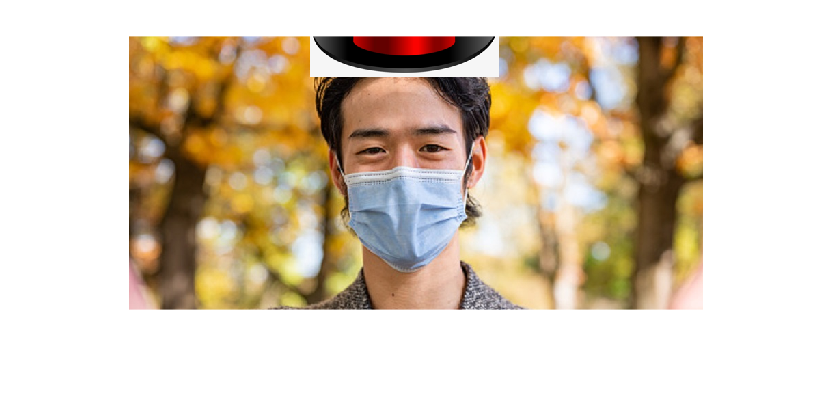

%openExample('vision/FaceTrackingUsingKLTExample')
person = imread("test_img3.jpg");
hat = imread("hat.png");

% Create a cascade detector object.
faceDetector = vision.CascadeObjectDetector();

% Read image
videoFrame = imread('test_img3.jpg');
% Pass image through model
bbox = step(faceDetector, videoFrame);

% Get x, y, width, height of bounding box
bbox_x = bbox(2, 1);
bbox_y = bbox(2, 2);
bbox_w = bbox(2, 3);
bbox_h = bbox(2, 4);

% bbox_w is the width of the hat
% new_h is the height of the hat
new_h = round(bbox_w / size(hat, 1) * size(hat, 2));
hat_resize = imresize(hat, [new_h, bbox_w]);

% Crop the hat in case it goes above the image of the person
hat_cropped = imcrop(hat_resize, [1 (new_h-bbox_y) bbox_w bbox_y]);

% Overlay images
output = person;
output(1:bbox_y+1, bbox_x:bbox_x + bbox_w - 1, :) = hat_cropped;
imshow(output);